clear all;
clc;

syms delta_1 delta_2 theta_1 theta_2 L_1 L_2 pi
% transformation matrices
for i = 1:5
    if i == 1
        alpha = 0; a = 0; d = 0; theta = delta_1;
        T1 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
            sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
            0 sin(alpha) cos(alpha) d;
            0 0 0 1];
    elseif i == 2
        alpha = -pi/2; a = 0; d = 0.5*((2*L_1*tan(0.5*theta_1))/theta_1); theta = -pi/2;
        T2 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
            sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
            0 sin(alpha) cos(alpha) d;
            0 0 0 1];
    elseif i == 3
        alpha = pi/2; a = 0; d = 0; theta = theta_1;
        T3 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
            sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
            0 sin(alpha) cos(alpha) d;
            0 0 0 1];
    elseif i == 4
        alpha = -pi/2; a = 0; d = 0.5*(((2*L_1*tan(0.5*theta_1))/theta_1)+(2*L_2*tan(0.5*theta_2)/theta_2)); theta = delta_2;
        T4 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
            sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
            0 sin(alpha) cos(alpha) d;
            0 0 0 1];
    elseif i == 5 %% the theta-term is different
        alpha = 0; a = 0.5*((2*L_2*tan(0.5*theta_2))/theta_2); d = 0; theta = theta_2-pi/2;
        T5 = [cos(theta) -cos(alpha)*sin(theta) sin(alpha)*sin(theta) a*cos(theta);
            sin(theta) cos(alpha)*cos(theta) -sin(alpha)*cos(theta) a*sin(theta);
            0 sin(alpha) cos(alpha) d;
            0 0 0 1];   
    end
end
trans = T1*T2*T3*T4*T5;
disp(trans);
Rx = trans(1:3,1)
Ry = trans(1:3,2)
Rz = trans(1:3,3)
px = trans(1,4);
py = trans(2,4);
pz = trans(3,4);
P = [px;py;pz];
% disp(pz);
% pose = transpose([px py pz]);
% disp(pose);

% simulate workspace
clear;
k = 1;
config = [];
cartesian = [];
L_1=50;
L_2=50;

while k <= 3000
    
    delta_1 = deg2rad(359).*rand();
    theta_1 = deg2rad(89).*rand();
    delta_2 = deg2rad(359).*rand();
    theta_2 = deg2rad(89).*rand();
    
    % position of the second segment
    px(k) = sin(delta_1)*sin(theta_1)*((L_1*tan(theta_1/2))/theta_1 + (L_2*tan(theta_2/2))/theta_2) + (L_2*tan(theta_2/2)*cos(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)))/theta_2 - (L_2*tan(theta_2/2)*sin(delta_1)*sin(theta_1)*sin(theta_2 - pi/2))/theta_2;
    py(k)=(L_2*tan(theta_2/2)*cos(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1)))/theta_2 - cos(delta_1)*sin(theta_1)*((L_1*tan(theta_1/2))/theta_1 + (L_2*tan(theta_2/2))/theta_2) + (L_2*tan(theta_2/2)*cos(delta_1)*sin(theta_1)*sin(theta_2 - pi/2))/theta_2;
    pz(k) = cos(theta_1)*((L_1*tan(theta_1/2))/theta_1 + (L_2*tan(theta_2/2))/theta_2) + (L_1*tan(theta_1/2))/theta_1 - (L_2*tan(theta_2/2)*cos(theta_1)*sin(theta_2 - pi/2))/theta_2 - (L_2*tan(theta_2/2)*cos(delta_2)*cos(theta_2 - pi/2)*sin(theta_1))/theta_2;
    
    % orientation of the second segment
    dir_alpha_Rx(k) = cos(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)) - sin(delta_1)*sin(theta_1)*sin(theta_2 - pi/2);
    dir_beta_Rx(k) = cos(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1)) + cos(delta_1)*sin(theta_1)*sin(theta_2 - pi/2);
    dir_gamma_Rx(k) = - cos(theta_1)*sin(theta_2 - pi/2) - cos(delta_2)*cos(theta_2 - pi/2)*sin(theta_1);
    dir_alpha_Ry(k) = - sin(theta_2 - pi/2)*(cos(delta_1)*sin(delta_2) + cos(delta_2)*sin(delta_1)*cos(theta_1)) - sin(delta_1)*cos(theta_2 - pi/2)*sin(theta_1);
    dir_beta_Ry(k) =  cos(delta_1)*cos(theta_2 - pi/2)*sin(theta_1) - sin(theta_2 - pi/2)*(sin(delta_1)*sin(delta_2) - cos(delta_1)*cos(delta_2)*cos(theta_1));
    dir_gamma_Ry(k) =  cos(delta_2)*sin(theta_1)*sin(theta_2 - pi/2) - cos(theta_1)*cos(theta_2 - pi/2);
    dir_alpha_Rz(k) = cos(delta_1)*cos(delta_2) - sin(delta_1)*sin(delta_2)*cos(theta_1);
    dir_beta_Rz(k) = cos(delta_2)*sin(delta_1) + cos(delta_1)*sin(delta_2)*cos(theta_1);
    dir_gamma_Rz(k) = sin(delta_2)*sin(theta_1);
    
    % covert rotation matrices to euler angles (second segment)
    rot = [dir_alpha_Rx(end,end) dir_alpha_Ry(end,end) dir_alpha_Rz(end,end);
        dir_beta_Rx(end,end) dir_beta_Ry(end,end) dir_beta_Rz(end,end);
        dir_gamma_Rx(end,end) dir_gamma_Ry(end,end) dir_gamma_Rz(end,end)];
    
    append_eul = rotm2eul(rot);
    
    % data preparation for the neural network
    append_config = [delta_1 theta_1 delta_2 theta_2];
    config = [config; append_config];
    append_cartesian = [px(k) py(k) pz(k)];
    cartesian = [cartesian; append_cartesian append_eul];
    % Hence, for the NN, the input and output shall be:
    input = cartesian;
    output = [config];
    k = k+1;
end

% plot workspace in jet color
figure
n = zeros(1,2000);
c = sqrt(px.^2+py.^2+pz.^2);
scatter3(px,py,pz,100,c,'.');
hold on
caxis auto;
colormap(jet);
hc = colorbar;
xlabel(hc,'{\itp}/mm')
axis equal;
xlabel('{\itx}/mm');
ylabel('{\ity}/mm');
zlabel('{\itz}/mm');
%axis([-80 80 0 80 0 100])
box on;

%section figure
figure
q = sqrt(px.^2+py.^2+pz.^2);
scatter3(px,py,pz,100,q,'.');
caxis auto;
colormap(jet);
colorbar;
axis equal;
axis([-85 85 -1 1  0 100])
box on;
hold on
view([0.0 0.0])

% plot workspace in all 2-color dots
figure
plot3(px,py,pz,'.');
P=[px',py',pz'];
figure

bdy = boundary(P);
trisurf(bdy,P(:,1),P(:,2),P(:,3),'Facecolor','blue','FaceAlpha',0.1);


%view([0.0 0.0])

axis equal
box on
hold on
%axis([-85 85 -1 1 0 100]);
%view([0.0 0.0])
%view([90.0 0.0])

% plot orientation of the distal segment
figure;
hx = quiver3(px,py,pz,dir_alpha_Rx,dir_beta_Rx,dir_gamma_Rx,'r','LineWidth',1,'AutoScaleFactor',2);
hold on;
hy = quiver3(px,py,pz,dir_alpha_Ry,dir_beta_Ry,dir_gamma_Ry,'g','LineWidth',1,'AutoScaleFactor',2);
hold on;
hz = quiver3(px,py,pz,dir_alpha_Rz,dir_beta_Rz,dir_gamma_Rz,'b','LineWidth',1,'AutoScaleFactor',2);
hold on;
axis equal;
box on;
grid on;
%axis([-85 85 -2 2  0 110]);
%view([0.0 0.0])

% create NN
net = feedforwardnet([18 18 18 18],'trainlm'); %% or use'trainscg'
%net = init(net);
net.trainParam.epochs = 5000;
net.trainParam.max_fail = 10;
net.trainParam.show = 1; % like a speed

%[ouput,settings] = processpca(input,'maxfrac',0.2);

% (this is where you can fine-tune your network structure)
net.trainParam.showCommandLine = true;
net.trainParam.goal = 0;
net.layers{1}.transferFcn = 'tansig'; %logsin, tansig, purelin;
net.layers{2}.transferFcn = 'tansig';
net.layers{3}.transferFcn = 'tansig';
net.layers{4}.transferFcn = 'tansig';
net.outputs{1}.processFcns = 'purelin';
[trainInd,valInd,testInd] = dividerand(k,0.7,0.15,0.15);
[net,tr] = train(net,input',output');
y = net(input');
save(['D:\localAddress\' ...
    'ik_net.mat'],'net');
perf = mse(net,config',y);
disp(perf)
% plottrainstate(tr);
% plotperform(tr);


% test
clear
clc
j = 1;
load 'ik_net.mat';
desire_config = [];
desire_cartesian = [];
L_1=50;
L_2=50;

while j <= 10000
    
    de_delta_1 = deg2rad(359).*rand();
    de_theta_1 = deg2rad(89).*rand();
    de_delta_2 = deg2rad(359).*rand();
    de_theta_2 = deg2rad(89).*rand();
    
    % position of the second segment
    de_px(j) = sin(de_delta_1)*sin(de_theta_1)*((L_1*tan(de_theta_1/2))/de_theta_1 + (L_2*tan(de_theta_2/2))/de_theta_2) + (L_2*tan(de_theta_2/2)*cos(de_theta_2 - pi/2)*(cos(de_delta_1)*sin(de_delta_2) + cos(de_delta_2)*sin(de_delta_1)*cos(de_theta_1)))/de_theta_2 - (L_2*tan(de_theta_2/2)*sin(de_delta_1)*sin(de_theta_1)*sin(de_theta_2 - pi/2))/de_theta_2;
    de_py(j)=(L_2*tan(de_theta_2/2)*cos(de_theta_2 - pi/2)*(sin(de_delta_1)*sin(de_delta_2) - cos(de_delta_1)*cos(de_delta_2)*cos(de_theta_1)))/de_theta_2 - cos(de_delta_1)*sin(de_theta_1)*((L_1*tan(de_theta_1/2))/de_theta_1 + (L_2*tan(de_theta_2/2))/de_theta_2) + (L_2*tan(de_theta_2/2)*cos(de_delta_1)*sin(de_theta_1)*sin(de_theta_2 - pi/2))/de_theta_2;
    de_pz(j) = cos(de_theta_1)*((L_1*tan(de_theta_1/2))/de_theta_1 + (L_2*tan(de_theta_2/2))/de_theta_2) + (L_1*tan(de_theta_1/2))/de_theta_1 - (L_2*tan(de_theta_2/2)*cos(de_theta_1)*sin(de_theta_2 - pi/2))/de_theta_2 - (L_2*tan(de_theta_2/2)*cos(de_delta_2)*cos(de_theta_2 - pi/2)*sin(de_theta_1))/de_theta_2;
    
    % orientation of the second segment
    de_dir_alpha_Rx(j) = cos(de_theta_2 - pi/2)*(cos(de_delta_1)*sin(de_delta_2) + cos(de_delta_2)*sin(de_delta_1)*cos(de_theta_1)) - sin(de_delta_1)*sin(de_theta_1)*sin(de_theta_2 - pi/2);
    de_dir_beta_Rx(j) = cos(de_theta_2 - pi/2)*(sin(de_delta_1)*sin(de_delta_2) - cos(de_delta_1)*cos(de_delta_2)*cos(de_theta_1)) + cos(de_delta_1)*sin(de_theta_1)*sin(de_theta_2 - pi/2);
    de_dir_gamma_Rx(j) = - cos(de_theta_1)*sin(de_theta_2 - pi/2) - cos(de_delta_2)*cos(de_theta_2 - pi/2)*sin(de_theta_1);
    de_dir_alpha_Ry(j) = - sin(de_theta_2 - pi/2)*(cos(de_delta_1)*sin(de_delta_2) + cos(de_delta_2)*sin(de_delta_1)*cos(de_theta_1)) - sin(de_delta_1)*cos(de_theta_2 - pi/2)*sin(de_theta_1);
    de_dir_beta_Ry(j) =  cos(de_delta_1)*cos(de_theta_2 - pi/2)*sin(de_theta_1) - sin(de_theta_2 - pi/2)*(sin(de_delta_1)*sin(de_delta_2) - cos(de_delta_1)*cos(de_delta_2)*cos(de_theta_1));
    de_dir_gamma_Ry(j) =  cos(de_delta_2)*sin(de_theta_1)*sin(de_theta_2 - pi/2) - cos(de_theta_1)*cos(de_theta_2 - pi/2);
    de_dir_alpha_Rz(j) = cos(de_delta_1)*cos(de_delta_2) - sin(de_delta_1)*sin(de_delta_2)*cos(de_theta_1);
    de_dir_beta_Rz(j) = cos(de_delta_2)*sin(de_delta_1) + cos(de_delta_1)*sin(de_delta_2)*cos(de_theta_1);
    de_dir_gamma_Rz(j) = sin(de_delta_2)*sin(de_theta_1);
    
    
    % covert rotation matrices to euler angles (second segment)
    de_rot = [de_dir_alpha_Rx(end,end) de_dir_alpha_Ry(end,end) de_dir_alpha_Rz(end,end);
        de_dir_beta_Rx(end,end) de_dir_beta_Ry(end,end) de_dir_beta_Rz(end,end);
        de_dir_gamma_Rx(end,end) de_dir_gamma_Ry(end,end) de_dir_gamma_Rz(end,end)];
    
    de_append_eul = rotm2eul(de_rot);
    
    % data preparation for the neural network
    de_append_config = [de_delta_1 de_theta_1 de_delta_2 de_theta_2];
    desire_config = [desire_config; de_append_config];
    de_append_cartesian = [de_px(j) de_py(j) de_pz(j)];
    desire_cartesian = [desire_cartesian; de_append_cartesian de_append_eul];
    de_input = desire_cartesian;
    de_output = [desire_config];
    j = j+1;
end

% compare the NN configuration space and arbitray configuration space
nn_config_ = net(de_input');
nn_config = nn_config_';

[r,p] = corrcoef(de_output,nn_config)
corr_coeff = 100*corr2(nn_config(1:4,1:end),de_output(1:4,1:end));
fprintf('The accuracy using correlation coefficient is %4.4f %%.', corr_coeff);

% correlation of cosine
nn_col = reshape(nn_config,[],1);
de_output_col = reshape(de_output,[],1);
corr_cos = 100*dot(nn_col,de_output_col)/(sqrt(sum(nn_col.*nn_col))*sqrt(sum(de_output_col.*de_output_col)));
fprintf('The accuracy using cosine correlation is %4.4f %%.', corr_cos);

% corr
[rho,pval] = corrcoef(de_output,nn_config);
disp(rho);
disp(pval);
fprintf('%.4f',pval(1,2));

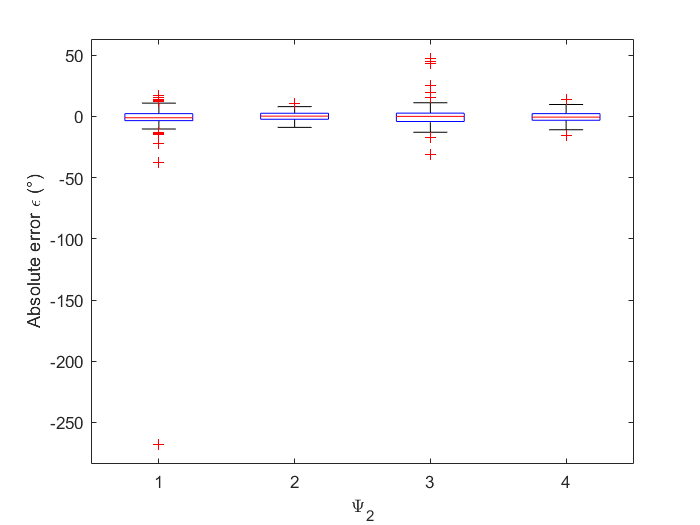

% absolute value
abs_delta_1 = [];
abs_theta_1 = [];
abs_delta_2 = [];
abs_theta_2 = [];

for w = 1:100
    abs_delta_1(w) = rad2deg(de_output(w,1)-nn_config(w,1));
    abs_theta_1(w) = rad2deg(de_output(w,2)-nn_config(w,2));
    abs_delta_2(w) = rad2deg(de_output(w,3)-nn_config(w,3));
    abs_theta_2(w) = rad2deg(de_output(w,4)-nn_config(w,4));
end
figure
boxplot([abs_delta_1', abs_theta_1', abs_delta_2', abs_theta_2']);
xlabel('\Psi_{2}')
ylabel('Absolute error \epsilon (°)')

% a = max(abs_delta_1)
% b = min(abs_delta_1)
% sort(abs_delta_1)
% bar(ans)
IQR = [prctile(abs_delta_1,95), prctile(abs_theta_1,95), prctile(abs_delta_2,95),...
    prctile(abs_theta_2,95);
    prctile(abs_delta_1,75), prctile(abs_theta_1,75), prctile(abs_delta_2,75),...
    prctile(abs_theta_2,75);
    prctile(abs_delta_1,50), prctile(abs_theta_1,50), prctile(abs_delta_2,50),...
    prctile(abs_theta_2,50);
    prctile(abs_delta_1,25), prctile(abs_theta_1,25), prctile(abs_delta_2,25),...
    prctile(abs_theta_2,25);
    prctile(abs_delta_1,5), prctile(abs_theta_1,5), prctile(abs_delta_2,5),...
    prctile(abs_theta_2,5)];
disp(IQR)

   11.4465    5.6590   17.4500    7.8344
    2.3323    2.5621    2.7336    2.3085
   -1.0466    0.2855    0.0932   -0.6048
   -3.4589   -2.3310   -4.1054   -3.1308
  -13.6099   -6.1763   -9.9956   -7.1780



QD = 0.5*[[prctile(abs_delta_1,75), prctile(abs_theta_1,75), prctile(abs_delta_2,75),...
    prctile(abs_theta_2,75)]-[prctile(abs_delta_1,25), prctile(abs_theta_1,25), prctile(abs_delta_2,25),...
    prctile(abs_theta_2,25)]]

QD =     2.8956    2.4465    3.4195    2.7196


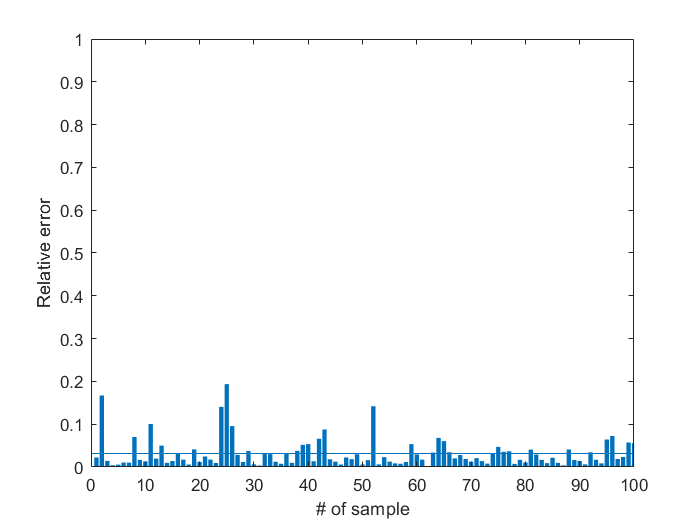

% compare and plot
for r = 1:(j-1)
    plot_corr_coeff(r) = corr2(nn_config(r,1:4),de_output(r,1:4));
    plot_corr_cos(r) = dot(nn_config(r,1:4),de_output(r,1:4))/...
        (sqrt(sum(nn_config(r,1:4).*nn_config(r,1:4)))*...
        sqrt(sum(de_output(r,1:4).*de_output(r,1:4))));
    relative_error(r) = abs(nn_config(r,1:4)-de_output(r,1:4))/(de_output(r,1:4));
end
figure;
bar(relative_error)
%%plot(relative_error,'-','Color','k')
%plot(plot_corr_coeff,'-','Color','k')
axis ([0 100 0 1]);
%hold on
line([0,100],[mean(relative_error),mean(relative_error)]);
xlabel('# of sample');
ylabel('Relative error');